# GPseudoRank by example

This vignette provides examples on 

1)  how to sample distributions of orders with GPseudoRank, and how to check convergence (example 1).

2) how to preprocess a larger data set using the mini-cluster approximation and how to use the setDefaultParams function (example 2).

3) how to select genes for pseudotime ordering (example 3).

## Example 1: Application to medium-sized scRNA-seq data set without mini-cluster approximation

We apply GPseudoRank to an scRNA-seq data set from 

Shalek et al. Single-cell RNA-seq reveals dynamic paracrine control of cellular variation Nature, 2104. 

Logarithms of expression levels were adjusted for cell size using the method introduced by 

S Anders and W Huber. Differential expression analysis for sequence count data. *Genome Biol*, 11(10):R106-R106, 2010. 

Exact replication of the study conducted in the paper requires 12 parallel chains. The larger number of parallel chains allows more exact convergence analysis, but for general use 1 chain is sufficient. To allow any assessment of convergence using the Gelman-Rubin statistic, at least 3-4 chains are required. We use fewer iterations than in the full analysis in the GPseudoRank paper, but a sufficient number to ensure convergence according to the Gelman-Rubin statistic (see also the convergence analysis at the end of this demonstration). 

clear all;
nChains = 4;% 12 for detailed convergence analysis; 1 sufficient for general 
% use

fHandle          = @pseudoRank; 
fileName         = 'Shalek.csv';

nSamples         = 100000;

Informative priors of the model are necessary to ensure it concentrates probability mass around the correct order and to avoid that a sampling or estimation algorithm gets trapped in local modes.

priorLogSDLength = 0.01;%standard deviation of prior of log-length scale, 
% recommended value
paramSamplingFreq =10; %sampling parameters for every kth order
verbose          = false; % Whether or not to print output to screen
initialise       = true;  % If you have to stop the sampler, and then 
% %wish to rerun at a later date, set this to false 
thinningFreq     = 10;     % If set to X, records every X-th sample
inputSeed        = NaN;  %use clock seed with chain-dependent offset

delta is a concentration parameter for the distribution to choose pairs of cells for moves 2 (swaps of cells close in terms of L1-distance) and move 3 (reversal of the path between such two cells); the lower delta, the less the concentration. Decrease delta in case of very high acceptance rates.

delta            = [1/4000,1/4000];

We apply each move of the proposal distribution with the same probability, except the reversal of the entire path, which is applied with a probability of 0.002.

pp               = [0.2495 0.2495 0.2495 0.2495 0.002];

Start with a random permutation:

permuteData      = true;

The times at which the cells were captured:

captureTimes = [repmat(0,[1,49]),repmat(1,[1,75]),repmat(2,[1,65]),...
    repmat(4,[1 60]),repmat(6,[1 58])];

With regInt = false, the pseudotime distances between cells are adapted to different speeds of biological development over the course of the reaction.

regInt           = false;%fixed recommended setting

permutationFileName = NaN: uses a random permutation, if the name of a .csv file was specified here, than the permutation specified in that file would be used.

permutationFileName = NaN;

The intial step size for the GP parameters, adapted during the first 5000 iterations. 

stepSize = [0.1,0.1];%fixed recommended setting

We use the default settings for the proposal distribution of the moves, as described in the GPseudoRank paper. 

%default
n0 = max(floor(307/4),1);
        n3 = max(1,floor(307/20));
        n3a = max(3,floor(307/12));
        kk = 1;
        jj = 1;

Running nChains MCMC chains in parallel with different random starting paths. This takes a bit of time (~25 minutes on the laptop on which it was tested, see 'elapsed time' below), but you may skip this and proceed to the post-processing using the output files provided. 

tic
parfor j = 1:nChains
feval(fHandle, 'Shalek.csv', j, nSamples, priorLogSDLength, verbose,...
    initialise,thinningFreq, paramSamplingFreq,stepSize,inputSeed, ...
    delta, pp,permuteData,captureTimes,regInt,permutationFileName,...
    5000,n0,n3,n3a,jj,kk);
end
toc
delete(gcp('nocreate'));

## Uncertainty of cell positions

The uncertainty of the cell positions changes over the course of the response to the infection.

First we compute the distribution of the posterior cell positions from the

output files of the GPseudoRank algorithm.

burnIn = 5000;%number of thinned samples to be discarded as burn-in
% 1:nChains refers to the identifieres of the MCMC chains and the initial
% permutations, the output is saved in the file 'ShalekUncertA.mat'
computePositionsPseudoRank('Shalek.csv',1:nChains,1:nChains,burnIn,...
    captureTimes,'ShalekUncertA.mat');

Plotting the posterior distributions of the cell positions: we see that the uncertainty decreases, once the reaction of the cells to the stimulant has set in, and becomes much larger again towards the end of the observed pseudotime range. This is relevant for downstream analyes such as the subsequent application of clustering or network methods for time series data, whose accuracy may benefit from focusing on the less uncertain part of the pseudotime series. 

set(0,'DefaultAxesFontName', 'Arial')
set(0,'DefaultAxesFontSize', 10)
set(0,'defaultfigurecolor',[1 1 1]);
load('ShalekUncertA.mat')
A = mean(posFreq,3);
% computing the average mean position
xx = mean(xx,2);
[sorted_xx xxI] = sort(xx);
figure()
colormap(hot);
imagesc(A(xxI,:)');
xlabel('cells ordered by mean position','FontSize',12);
ylabel('position (distribution)','FontSize',12);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


set(gca,'YDir','normal')

Elapsed time is 1619.934508 seconds.


ax= gca;
c=colorbar;

## Uncertainty of the distributions of the orders

The first step is to compute the L1-distances of each posterior sample of cell positions from a reference order (1:307). The reference order may be any arbitray order. The plot illustrates the uncertainty of the order of the cells.

nSamplesThinned = floor(nSamples/thinningFreq);
distsL1a = zeros(nChains,nSamplesThinned);
permuts1 = zeros(nSamplesThinned,307);%307 is the total number of cells

for j = 1:nChains
    orders1 = csvread(sprintf('Shalek_Results_Orders_Chain%d.csv',j));
    permStart1 = csvread(sprintf('Shalek_Permutation%d.csv',j));
   for k = 1:nSamplesThinned
        permuts1(k,:)  = permStart1(orders1(k,:));
    end
  
    corrCap1 = corr(permuts1',captureTimes');
    permuts1(corrCap1<0,:) = permuts1(corrCap1<0,end:-1:1);
    distsL1a(j,:) = distFromRefOrder(permuts1,1:307);
end
csvwrite('ShalekDistFromRefL1Irreg.csv',distsL1a);

Now we illustrate the densities of the L1-distances using a histogram:

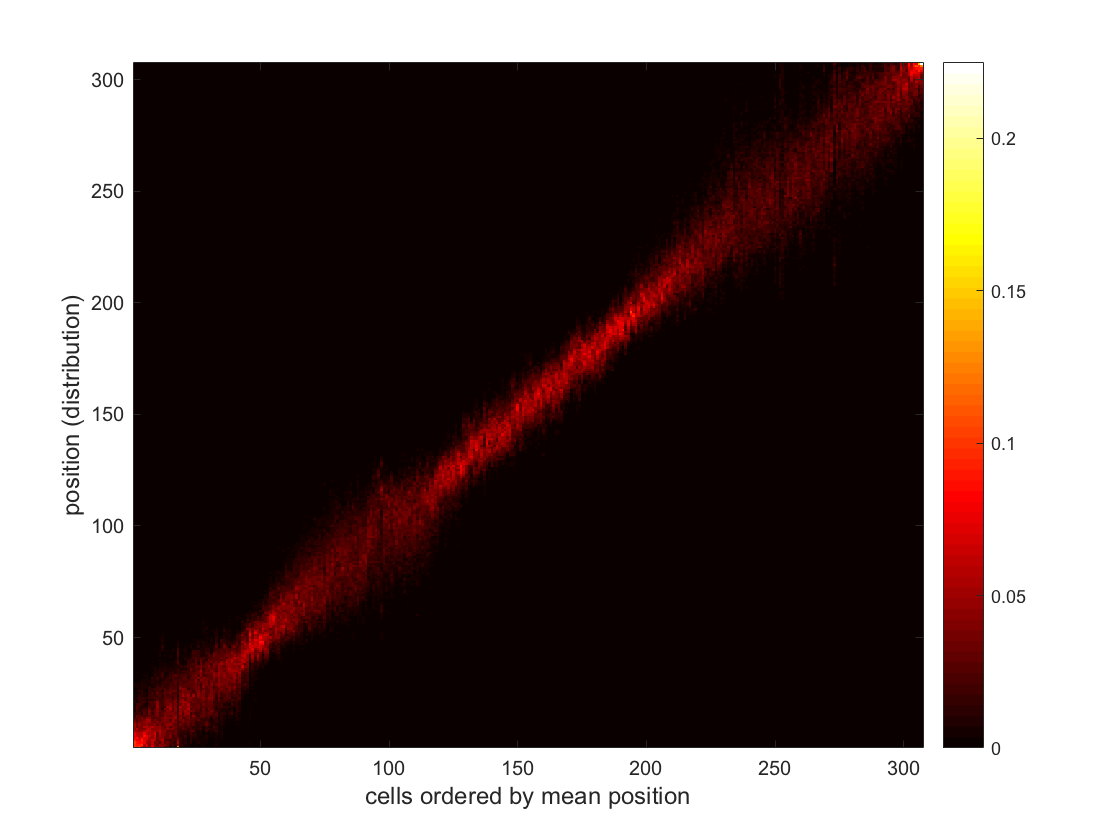

figure();
A = dlmread('ShalekDistFromRefL1Irreg.csv',',',...
    [0 burnIn nChains-1 nSamplesThinned-1]);
a = min([min(A)]);
b = max([max(A)]);
xlabel('$L^1$-distance','FontSize',10,'Interpreter','Latex');
set(gcf, 'PaperUnits', 'centimeters');

histogram(A(:),'BinEdges', a:30:b,'FaceAlpha',0.3);
set(gca,'box','off');

## Convergence analysis

First we compute the Gelman-Rubin Rhat statistic for the L1-distances of the sampled cell positions from the reference permutation 1:307.

Run the following code in R to compute the Gelman-Rubin statistic, using the coda package:

`library(coda)`

x1 = read.csv("ShalekDistFromRefL1Irreg.csv",header = F) 

x1MC = as.mcmc.list(lapply(as.data.frame(t(x1)), mcmc)) 

X1 = gelman.plot(x1MC,transform = F,autoburnin = T,bin.width = 20,max.bins=497) 

write.csv(X1$shrink[,,1],"GRShalek.csv")

We also compute the Gelman-Rubin statistic for the log-likelihoods.

First combine the log-likelihoods of the individual chains in a single file:

LksShalek = [];
for j = 1:nChains
File = sprintf('Shalek_Results_Chain%d.csv',j);  
 xx = dlmread(File,',',[0 0 nSamplesThinned-1 0]);
 LksShalek = [LksShalek xx];
end
csvwrite('LksShalek.csv',LksShalek);

Run the following code in R to compute the Gelman-Rubin statistic, using the coda package:

`library(coda) `

x1 = read.csv("LksShalek.csv",header = F) 

x1MC = as.mcmc.list(lapply(as.data.frame((x1)), mcmc)) 

XX1 = gelman.plot(x1MC,transform = F,autoburnin = T,bin.width = 20,max.bins=497) 

write.csv(XX1$shrink[,,1],"GRShalek_Lks.csv")

Now we can plot the Gelman-Rubin statistics. For convergence, a value for the statistic below 1.1 is preferable, though 1.2 is considered sufficient in

SP Brooks and A Gelman. General methods for monitoring convergence of iterative simulations. 

*J Comput Graph Stat*, 7(4): 434:455, 1998. 

1.1 is recommended in 

A Gelman and K Shirley. Inference from simulations and monitoring convergence. In S Brooks, A Gelman, G Jones, and X-L Meng, editors, *Handbook of Markov Chain Monte Carlo*, volume 6, pages 163:174. CRC, Boca Raton, 2011. 

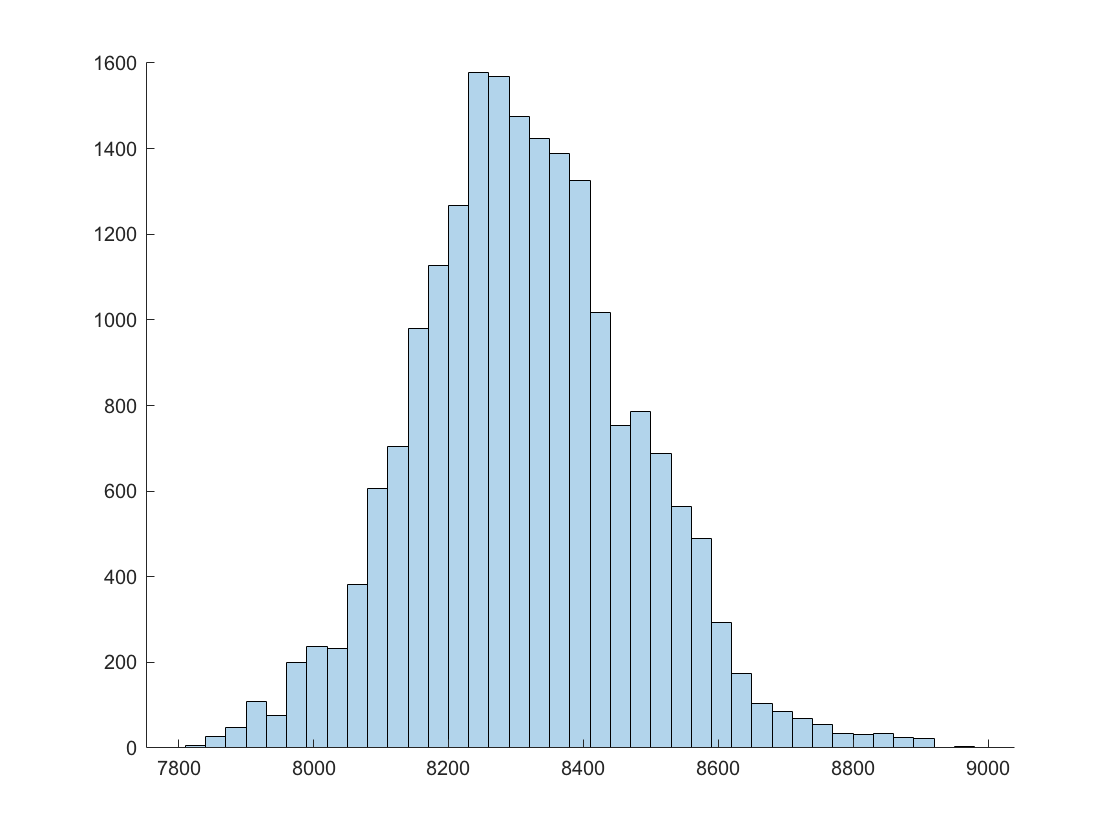

A = importdata('GRShalek.csv');
GRL1 = A.data;
GRLk = csvread('GRShalek_Lks.csv',1,1);
stepSize =  cellfun(@str2num,A.textdata(2:end,1));
figure();
plot(stepSize,GRL1,'LineWidth',2);
hold on;
plot(stepSize,GRLk,'LineWidth',2);
hold on;
h0 = refline([0,1.2]);
h0.LineWidth = 2;
h0.Color = 'c';

h0.LineStyle = '--';
h1 = refline([0,1.1]);
h1.LineWidth = 2;
h1.Color = 'g';
h1.LineStyle = '--';
ylim([1,1.7]);
xlabel('sample(thinning = 10)','FontSize',10);
ylabel('$\hat{R}$','Interpreter','Latex','FontSize',10);
set(gca,'box','off');
ax=gca;
leg = legend('L^1-distances','log-Lk','1.2-level','1.1-level');
leg.FontSize = 11

## Example 2: mini-cluster approximation and default parameter settings for the proposal moves

Simulating a data set with 5000 cells

logSw2 = randn(1,100)*0.1 + log(sqrt(1));
sw2 = exp(2*logSw2);
logL = randn(1,100).*0.1+log(0.4);
l = exp(logL);
logSe2 = randn(1,100)*0.1 + log(sqrt(0.5));
se2 = exp(2*logSe2);
ppar = [logSw2;logL;logSe2];
simGPIndiv(5000,sw2,l,se2,'sim_Example1.csv','tau_Example1.csv',false,'uniform');

Applying the mini-cluster approximation

%assuming there are capture times
captureTimes = [zeros(1,1000),ones(1,1000),repmat(2,1,1000),repmat(3,1,1000),repmat(4,1,1000)];
miniclust('sim_Example1.csv',captureTimes);

Finding the default parameters for this data set:

[n0,n3,n3a,jj,kk,delta,pp]  = setDefaultParams('sim_Example1KM.csv',true);

delete -r 'sim_Example1*'

## Example 3: selecting genes

Simulating a data set with 5000 genes

logSw2 = randn(1,5000)*0.1 + log(sqrt(1));
sw2 = exp(2*logSw2);
logL = randn(1,5000).*0.1+log(0.4);
l = exp(logL);
logSe2 = randn(1,5000)*0.1 + log(sqrt(0.5));
se2 = exp(2*logSe2);
ppar = [logSw2;logL;logSe2];
simGPIndiv(60,sw2,l,se2,'sim_Example1.csv','tau_Example1.csv',false,'uniform');

Selecting genes with capture times using anova to test difference between mean expressions for different capture times

captureTimes = [zeros(1,20),ones(1,20),repmat(2,1,20)];
selGenes('sim_Example1.csv',captureTimes);

Selecting genes without capture times

captureTimes = [zeros(1,20),ones(1,20),repmat(2,1,20)];
selGenes('sim_Example1.csv');

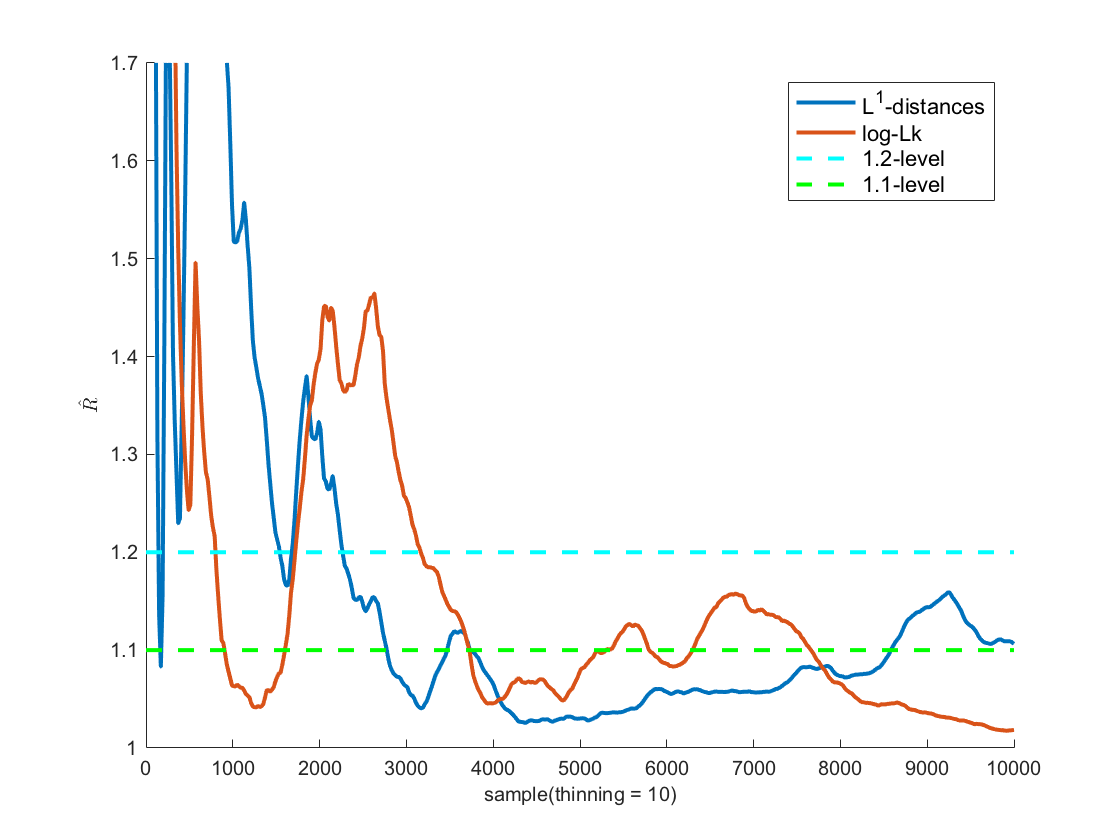

delete 'sim_Example1*'